clc; clear; 
close all;

% mental notes: 
% columns = i direction
% rows = j direction

% Grid/mesh
% ni points in x~i direction
% nj points in y~j direction
dx = .031;
x = 0:dx:pi;
ni = length(x);
dy = .031;
y = 0:dy:2*pi;
nj = length(y);

% Pre-allocate memory for u(x,y), serving as initial guess as well
u = zeros(nj,ni);

% Boundary Equations
u(1,:) = sin(x).^2; % bottom surface 
u(:,1) = 0; % left surface
u(end,:) = 0; % top surface
u(:,end) = 0; % right surface

% setting up tridiagonal system
alpha = 1/dy^2;
beta = -2/dy^2 - 2/dx^2;
gamma = -1/dx^2;

a = alpha.*ones(nj,1);
b = beta.*ones(nj,1);
c = alpha.*ones(nj,1);
b(1) = 1; b(end) = 1; c(1) = 0; a(end) = 0;

% Iterations and Thomas3
cor = 1;
tol = 1e-10;
w = 1.9;
unew = u;
iterations = 0;
tstart = tic;
while cor > tol
    uvold = unew;
    for i=2:ni-1
        d = gamma.*(unew(:,i-1)+uvold(:,i+1));
        d(1) = unew(1,i);
        d(nj) = unew(end,i);
        uv = w.*THOMAS3(a,b,c,d,nj)'+ (1-w).*uvold(:,i);
        unew(:,i) = uv;
    end
    cor(iterations+1,1) = max(max(abs(unew-uvold)));
    iterations = iterations+1;
end
u = unew;
tend = toc(tstart)

tend = 10.5709

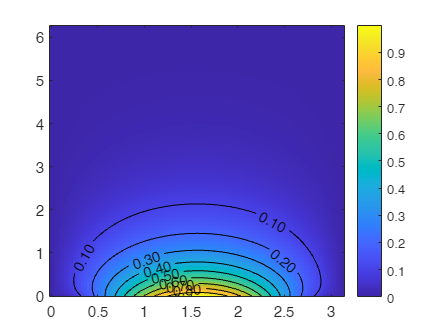

iterations = linspace(1,iterations,iterations);

imagesc(x,y,u)
set(gca,'Ydir','normal')
hold on;
contour(x,y,u,'k','ShowText','on','LabelFormat','%.2f')
hold off;
colorbar

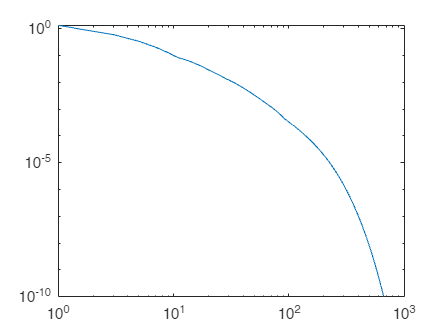


loglog(iterations,cor)

function x = THOMAS3(a,b,c,d,n)

    %initial condition
    bbar(1) = b(1);
    cbar(1) = c(1);
    dbar(1) = d(1);

    %making upper triangle
    for i = 2:n
        multiplier = a(i)./bbar(i-1);
        abar(i) = a(i) - bbar(i-1).*multiplier;
        bbar(i) = b(i) - cbar(i-1).*multiplier;
        cbar(i) = c(i);
        dbar(i) = d(i) - dbar(i-1).*multiplier;
    end
    
    %initialize x of size n
    x = ones(1,n);

    %initialize end condition
    x(n) = dbar(n)/bbar(n);

    % Upward substitution AKA zip it up
    for i = n-1:-1:1
        x(i) = (dbar(i)-(cbar(i)*x(i+1)))/bbar(i);
    end
end
